# [Regression Overview](https://apmonitor.com/pds/index.php/Main/RegressionOverview)

Regression is a type of supervised learning that predicts continuous output values from a set of input features. The goal of regression is to build a model that can accurately predict the target variable for new, unseen data.

There are many different algorithms that can be used for regression, and some of the most commonly used ones include:

1️⃣ [**Linear Regression**](https://apmonitor.com/pds/index.php/Main/LinearRegression): Linear regression is a simple and widely used approach to regression that models the relationship between the input and output variables as a linear function. Linear regression is easy to interpret and computationally efficient, but it may not perform well for nonlinear relationships between variables.

2️⃣ [**k-Nearest Neighbors**](https://apmonitor.com/pds/index.php/Main/KNearestNeighborsRegression): k-Nearest Neighbors (k-NN) is a non-parametric algorithm that predicts the target value for a new data point by finding the k closest data points in the training set and averaging their target values. k-NN is simple and easy to implement, but it can be computationally expensive for large datasets.

3️⃣ [**Support Vector Regressor**](https://apmonitor.com/pds/index.php/Main/SupportVectorRegressor): Support Vector Regression (SVR) is a variant of support vector machines that can be used for regression problems. It works by finding the hyperplane that maximally separates the data points while minimizing the error on the training data.

4️⃣ [**Gaussian Processes**](https://apmonitor.com/pds/index.php/Main/GaussianProcessRegression): Gaussian Processes (GP) is a probabilistic approach to regression that models the relationship between the input and output variables as a Gaussian distribution. It is a flexible method that can be used to model complex, nonlinear relationships between variables, and can be used for both regression and classification problems.

5️⃣ [**Neural Network Regressor**](https://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork): Neural networks are a powerful class of models that can be used for regression and classification tasks. They are highly flexible and can model complex, nonlinear relationships between variables, but can be computationally expensive and require large amounts of training data.

6️⃣ [**XGBoost Regressor**](https://apmonitor.com/pds/index.php/Main/XGBoostRegressor): XGBoost is a popular algorithm for regression and classification that uses a gradient boosting approach to iteratively improve the performance of the model. It is highly accurate and can handle large datasets with many features, but can be computationally expensive.

Other regression algorithms include decision trees, random forests, and Bayesian regression, among others. The choice of algorithm depends on the specific problem and the characteristics of the data, and it is often useful to try multiple algorithms and compare the performance.

#### 1D Regression Example

A linear regression has 100 sample points with one feature (*X*), one output label (*y*), and random variations in the data (*noise*). To perform the Linear Regression with the app, [click here](https://www.mathworks.com/help/stats/regression-learner-app.html).

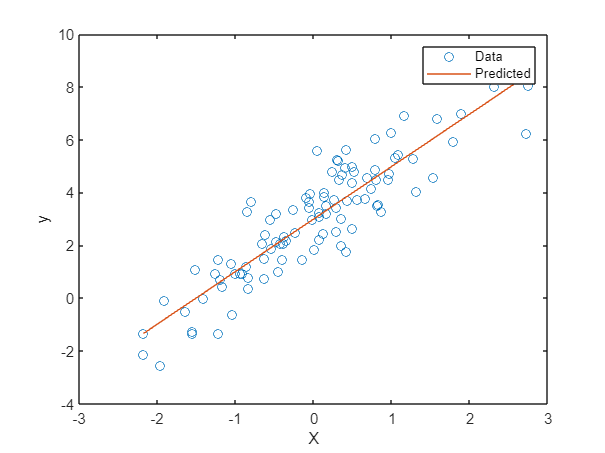

% Generate sample data
X = randn(100, 1); % generate 100 random samples from a standard normal distribution
w_true = [2; 3]; % true weight vector
y = X*w_true(1) + w_true(2) + randn(100, 1); % generate output y with added noise

% Fit a Linear regression model
model = fitlm(X,y);

% Plot the data and the fitted line
plot(X,y,'o');
hold on;
plot(X,predict(model,X),'-');
ylabel('y');
xlabel('X');
legend('Data','Predicted')
hold off;

#### 2D Regression Example

Another linear regression also has 100 sample points, but with two features (*X*). A 3-dimensional plot is used to view the relationship between the two features and the output.

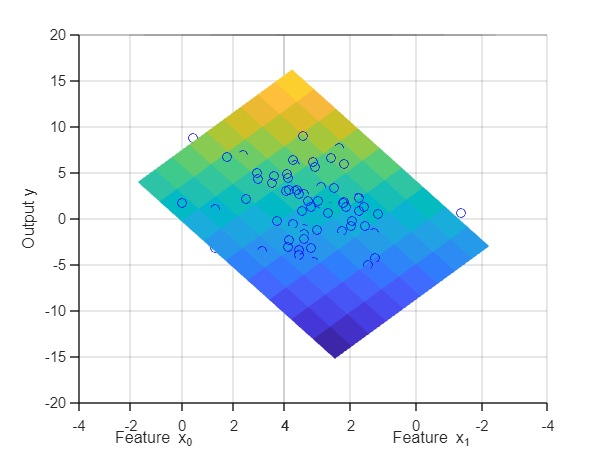

% Generate sample data
X = randn(100, 2); % generate 100 random samples with 2 features each
w_true = [2; 3]; % true weight vector
y = X*w_true + randn(100, 1)*2; % generate output y with added noise

% Fit a Linear regression model
model = fitlm(X,y);

% Plot the data and the fitted surface
figure;
scatter3(X(:, 1), X(:, 2), y, 'blue');
hold on;
[x0_surf, x1_surf] = meshgrid(linspace(-3, 3, 10), linspace(-3, 3, 10));
Xp = [x0_surf(:), x1_surf(:)];
y_surf = predict(model, Xp);
y_surf = reshape(y_surf, size(x0_surf));
surf(x0_surf, x1_surf, y_surf, 'EdgeColor', 'none');
xlabel('Feature x_0');
ylabel('Feature x_1');
zlabel('Output y');
hold off;

#### Multiple Regression

Regression results, especially with 3+ features, can be viewed with a parity plot to show the performance of the regression fit. Separate train (80%) and test sets (20%) are split to fit and evaluate the performance on separate data.

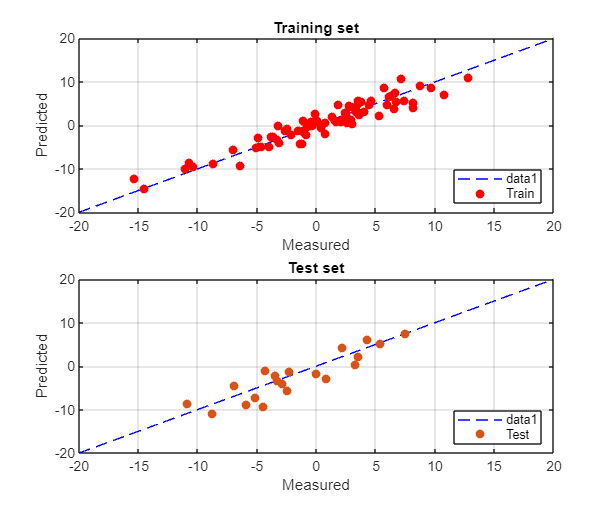

% Generate random data
n = 100; % number of samples
X = randn(n, 5); % generate 100 random samples with 5 features each
w_true = [2; 3; -1; 0; 4]; % true weight vector
y = X*w_true + randn(n, 1)*2; % generate output y with added noise

% Split data into train and test
[trainID,~,testID] = dividerand(n,0.8,0,0.2);
x_train = X(trainID,:);
y_train = y(trainID,:);
x_test = X(testID,:);
y_test = y(testID,:);

% Fit a linear regression model
model = fitlm(x_train,y_train);

% Plot the data
figure('Position', [100 100 600 500]);

subplot(2,1,1);
%
plot([-20,20],[-20,20],'b--');
hold on;
yp = predict(model, x_train);
scatter(y_train, yp, 'red', 'filled', 'DisplayName', 'Train');
grid on; box on;
xlabel('Measured'); ylabel('Predicted'); title('Training set');
legend('Location', 'southeast');

subplot(2,1,2);
plot([-20,20],[-20,20],'b--');
hold on;
yp = predict(model, x_test);
scatter(y_test, yp, 'filled', 'DisplayName', 'Test');
grid on; box on;
xlabel('Measured'); ylabel('Predicted'); title('Test set');
legend('Location', 'southeast');
hold off;